# Pràctica 7. Exercici 2

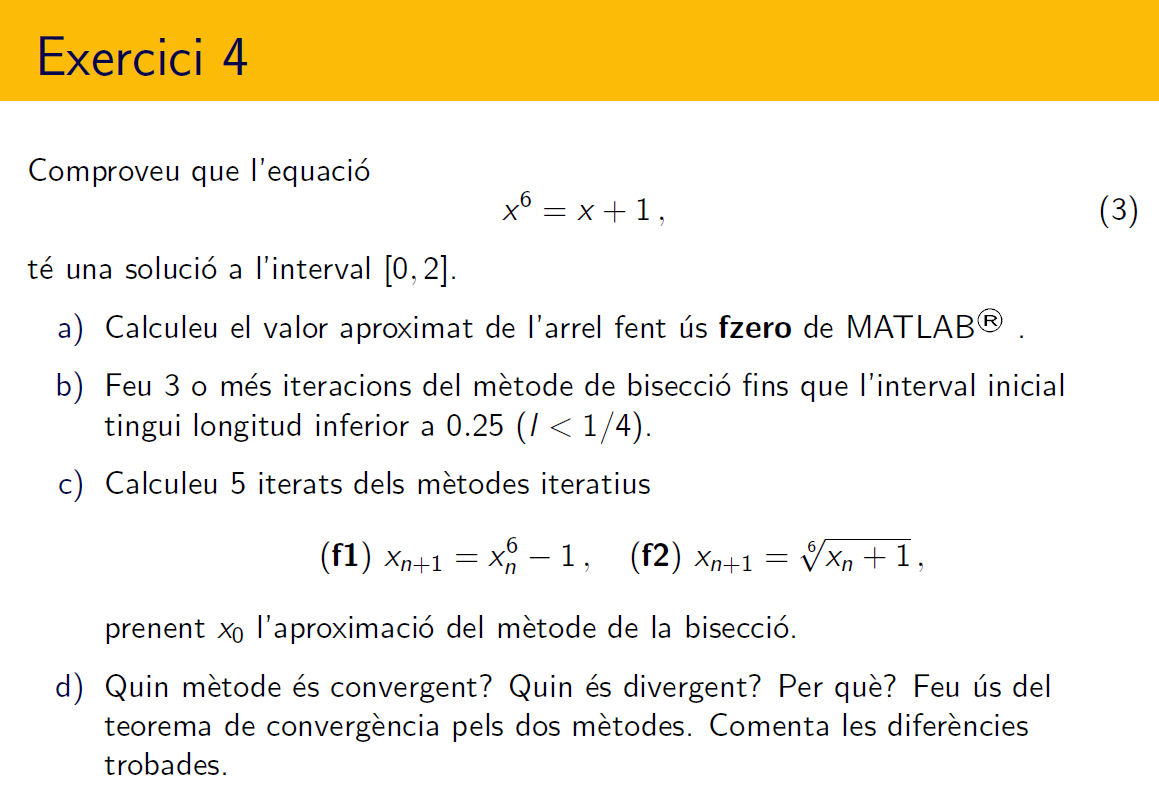

================================================================================

- `Comproveu que l'equació té una solució a l'interval [0,2]`

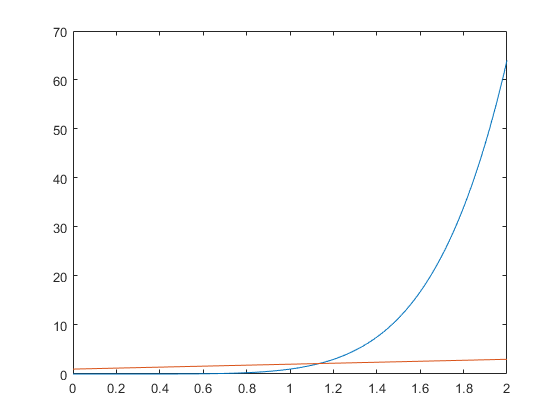

t = linspace(0,2);
plot(t,t.^6,t,t+1)

f = @(x) x.^6-x-1;
t = (0:0.25:2)';
disp([t,f(t)])

            0           -1
         0.25      -1.2498
          0.5      -1.4844
         0.75       -1.572
            1           -1
         1.25       1.5647
          1.5       8.8906
         1.75       25.973
            2           61



- `Determineu un subinterval [a_0,b_0] de longitud l=0.25 amb canvi de signe de la funció associada a l'equació `$x^6=x+1$.

tol = 0.25;
x0 = bisect(f,0,2,3,tol)

    k          x                   f                   l
        0.000000000000000  -1.000000000000000                    
        2.000000000000000  61.000000000000000                    
    1   1.000000000000000  -1.000000000000000   1.000000000000000
    2   1.500000000000000   8.890625000000000   0.500000000000000
    3   1.250000000000000   1.564697265625000   0.250000000000000
        1.125000000000000  -0.097713470458984   0.125000000000000


x0 =         1.125


- `Preneu `$x_0$` el punt mig de l'interval [a_0,b_0] de l'apartat anterior i calculeu 5 iterats per cadascun dels mètodes iteratius: `$
\mathbf{(f1)}~x_{n+1} = x_n^6-1\,,\qquad \mathbf{(f2)}~x_{n+1} = \sqrt[6]{x_n+1}\,,$ 

g1 =@(t) t^6-1;
x = x0;
for n = 1:5
    x = g1(x);
end
tolf = abs(f(x))

tolf =      1


fprintf('En n = 5 iteracions del mètode f1 el valor obtingut és x = %d',x)

En n = 5 iteracions del mètode f1 el valor obtingut és x = -1

g2 =@(t) nthroot(t+1,6);
x = x0;
for n = 1:5
    x = g2(x)
end

x =        1.1339


x =        1.1346


x =        1.1347


x =        1.1347


x =        1.1347


tolf = abs(f(x))

tolf =    5.4709e-07


fprintf('En n = 5 iteracions del mètode f1 el valor obtingut és x = %d',x)

En n = 5 iteracions del mètode f1 el valor obtingut és x = 1.134724e+00

- `Calculeu el valor aproximat fent ús ``fzero`` de MATLAB®. `

a = 1; b = 1.25;
[x fval] = fzero(f,[a,b]);
alpha = x, tolf = abs(fval)

alpha =        1.1347


tolf =    8.8818e-16


- `Quin m\ètode és convergent? Quin és divergent? Per què? Feu ús del teorema de convergència pels dos esquemes iteratius, (``f1``) i (``f2``). Comenta les diferències trobades.`

syms t
dg1(t) = diff(g1,t), dg2(t) = diff(g2,t)

$$dg1(t) = 6\,t^{5}$$

$$dg2(t) = \frac{\sqrt[{6}]{t+1}}{6\,\left(t+1\right)}$$

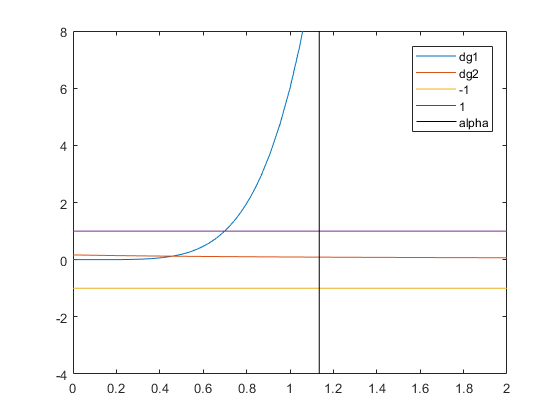

fplot([dg1,dg2,-1,1],[0,2]), ylim([-4 8])
hold on
line([alpha,alpha],[-4,8],'Color','k'),hold off
legend('dg1','dg2','-1','1','alpha','Location','best')

consistencia1 = g1(alpha) - alpha, consistencia2 = g2(alpha) - alpha

consistencia1 =   -8.8818e-16


consistencia2 =      0


k = [double(dg1(1)), double(dg2(1))]

k =             6     0.093539


% divergent f1, convergent f2